## Project 1

### Sentences for pro 1: ‘C_01_01.wav’ & ‘C_01_02.wav’ 

### Task 1 

#### • Set LPF cut-off frequency to 50 Hz. 将低通滤波截止频率设置为50Hz。

#### • Implement tone-vocoder by changing the number of bands to N=1, N=2, N=4, N=6, and N=8.

#### • Save the wave files for these conditions, and describe how the number of bands affects the intelligibility (i.e., how many words can be understood) of synthesized sentence.

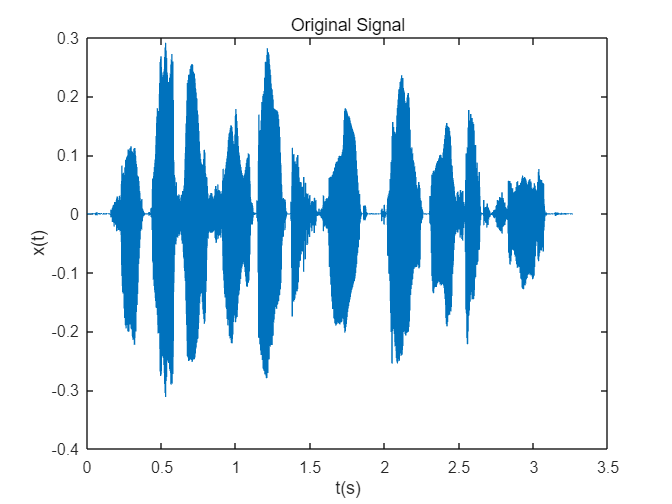

[x1,~]=audioread("C:\Users\Lenovo\Desktop\Signals and system\Project1\C_01_01.wav");
[x2,fs]=audioread("C:\Users\Lenovo\Desktop\Signals and system\Project1\C_01_02.wav");

fcut=50;

figure
plot(xTime(x1,fs),x1),title('Original Signal'),xlabel('t(s)'),ylabel("x(t)")

SSN=createSSN(x1,fs);

Frequency-to-place mapping in cochlea:


$$f=165\ldotp 4\times \left({10}^{0\ldotp 06\cdot d} -1\right)$$


where $f$ is -3 dB cut-off frequency, and $d$ is the distance (in millimeter) along the cochlea.

**Task1**

n1=4,n2=4;%具体优化值有待讨论？？？？？？？？？？？？？？？？？？

n1 = 4

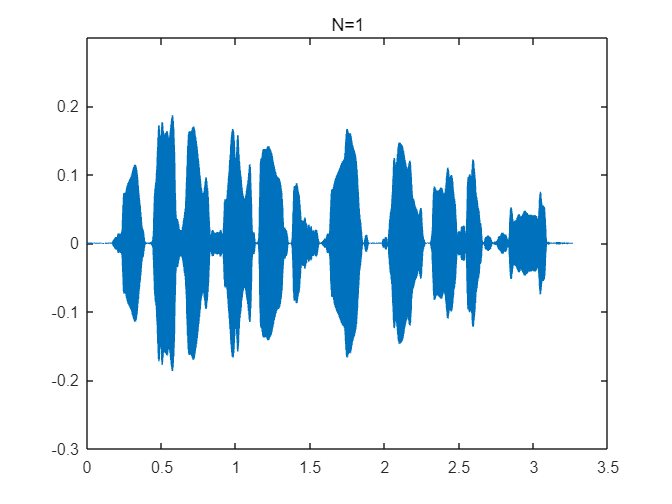


%set the cut-off frequency to 50Hz
y1=Synthesize(x1,1,n1,n2,50,fs);
y2=Synthesize(x1,2,n1,n2,50,fs);
y4=Synthesize(x1,4,n1,n2,50,fs);
y6=Synthesize(x1,6,n1,n2,50,fs);
y8=Synthesize(x1,8,n1,n2,50,fs);

figure
plot(xTime(y1,fs),y1),title('N=1'),ylim([-0.3,0.3])

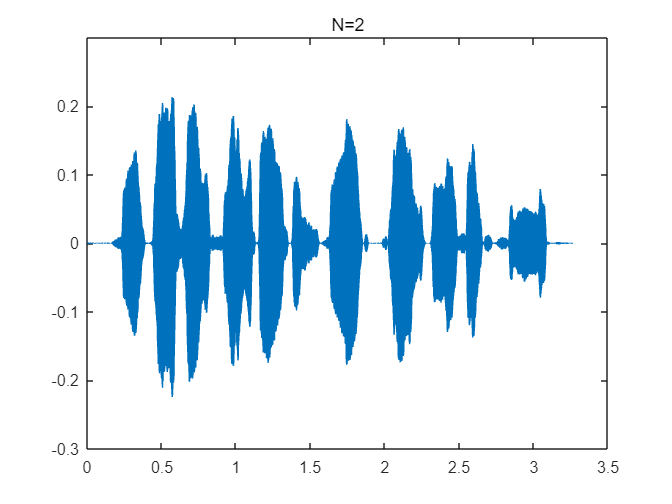

plot(xTime(y2,fs),y2),title('N=2'),ylim([-0.3,0.3])

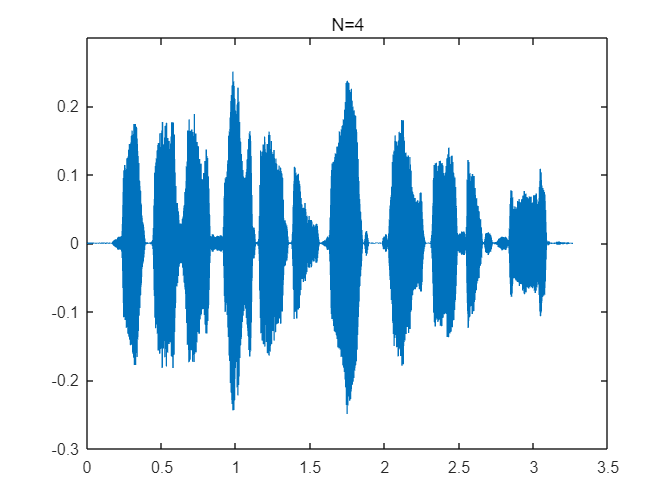

plot(xTime(y4,fs),y4),title('N=4'),ylim([-0.3,0.3])

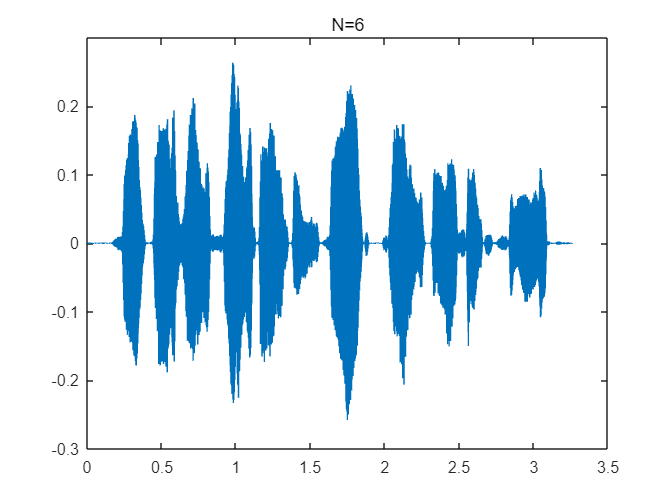

plot(xTime(y6,fs),y6),title('N=6'),ylim([-0.3,0.3])

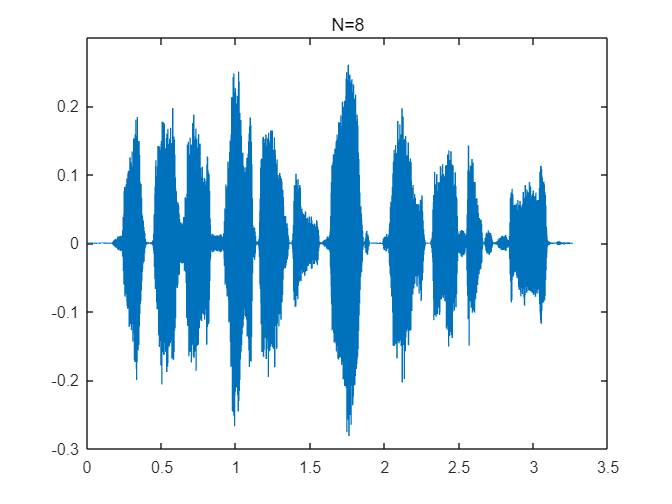

plot(xTime(y8,fs),y8),title('N=8'),ylim([-0.3,0.3])

**Task2**

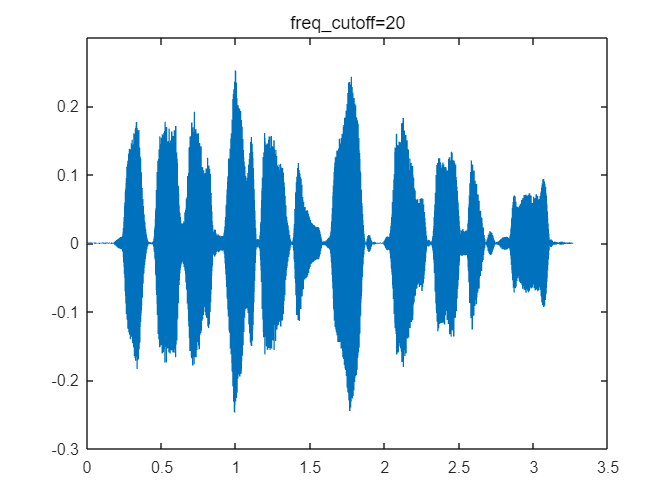

%set the number of bands to N=4
y_fs_20=Synthesize(x1,4,n1,n2,20,fs);
y_fs_50=Synthesize(x1,4,n1,n2,50,fs);
y_fs_100=Synthesize(x1,4,n1,n2,100,fs);
y_fs_400=Synthesize(x1,4,n1,n2,400,fs);

figure
plot(xTime(y_fs_20,fs),y_fs_20),title('freq\_cutoff=20'),ylim([-0.3,0.3])

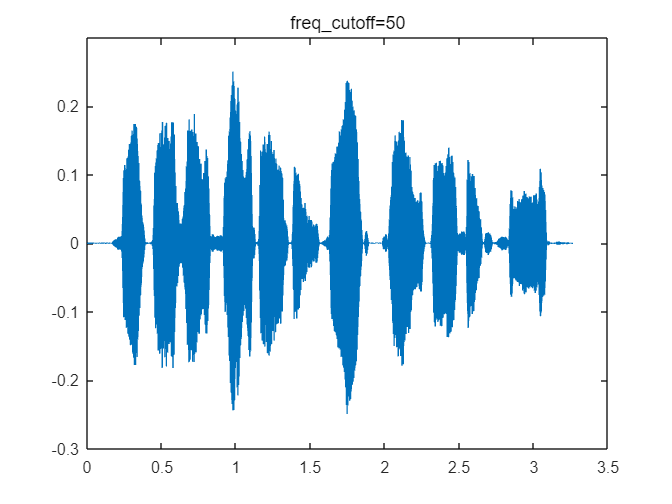

plot(xTime(y_fs_50,fs),y_fs_50),title('freq\_cutoff=50'),ylim([-0.3,0.3])

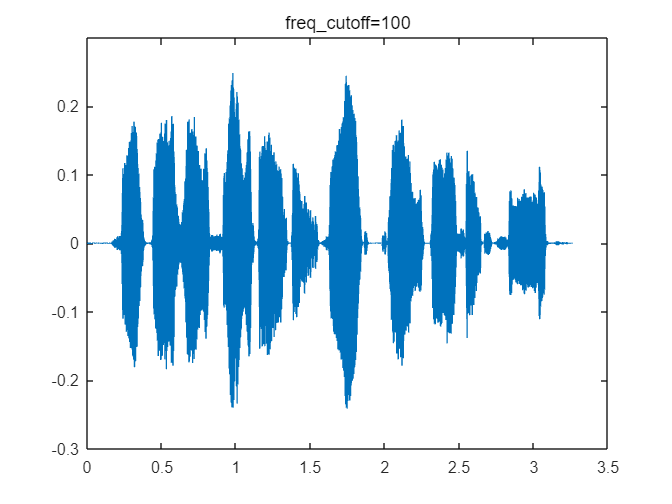

plot(xTime(y_fs_100,fs),y_fs_100),title('freq\_cutoff=100'),ylim([-0.3,0.3])

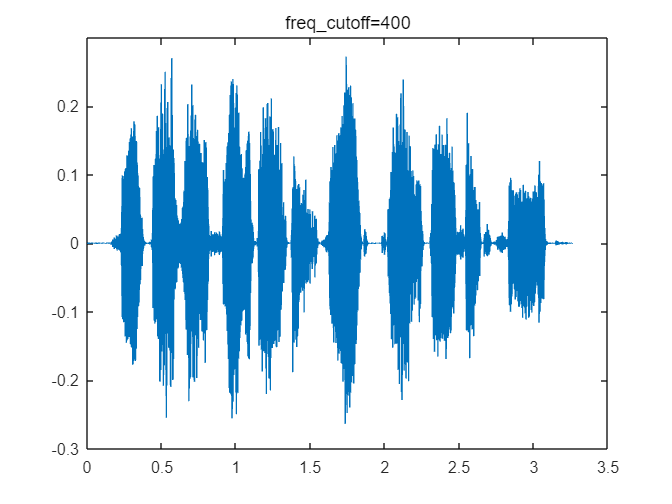

plot(xTime(y_fs_400,fs),y_fs_400),title('freq\_cutoff=400'),ylim([-0.3,0.3])

**Task3**

SNR=-5

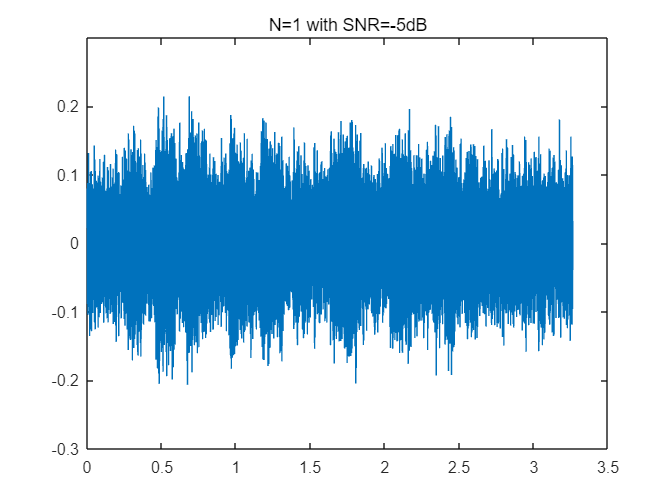

SSN=SSN/norm(SSN)*norm(x1)*10^0.25;

%set the cut-off frequency to 50Hz
y1_with_SSN=Synthesize(x1,1,n1,n2,50,fs)+SSN;
y2_with_SSN=Synthesize(x1,2,n1,n2,50,fs)+SSN;
y4_with_SSN=Synthesize(x1,4,n1,n2,50,fs)+SSN;
y6_with_SSN=Synthesize(x1,6,n1,n2,50,fs)+SSN;
y8_with_SSN=Synthesize(x1,8,n1,n2,50,fs)+SSN;

%Energy normalization
y1_with_SSN=y1_with_SSN/norm(y1_with_SSN)*norm(x1);
y2_with_SSN=y2_with_SSN/norm(y2_with_SSN)*norm(x1);
y4_with_SSN=y4_with_SSN/norm(y4_with_SSN)*norm(x1);
y6_with_SSN=y6_with_SSN/norm(y6_with_SSN)*norm(x1);
y8_with_SSN=y8_with_SSN/norm(y8_with_SSN)*norm(x1);

figure
plot(xTime(y1_with_SSN,fs),y1_with_SSN),title('N=1 with SNR=-5dB'),ylim([-0.3,0.3])

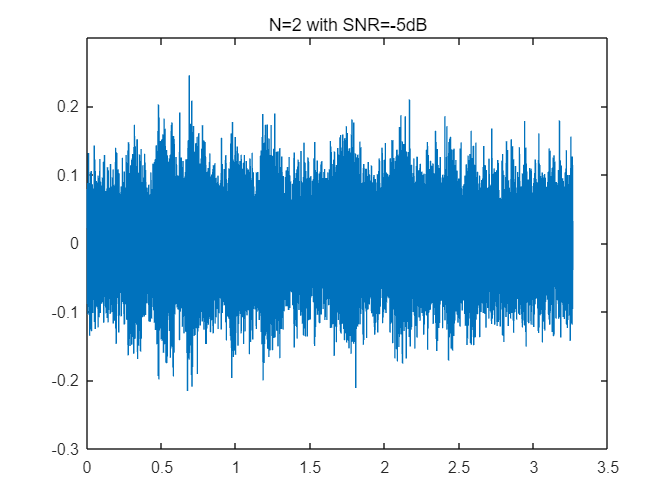

plot(xTime(y2_with_SSN,fs),y2_with_SSN),title('N=2 with SNR=-5dB'),ylim([-0.3,0.3])

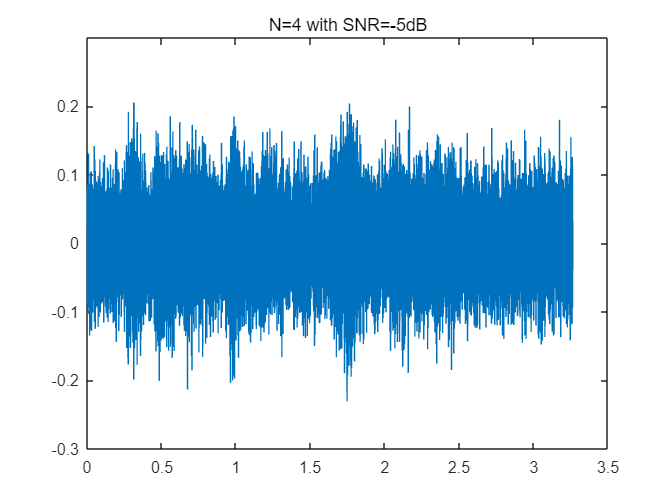

plot(xTime(y4_with_SSN,fs),y4_with_SSN),title('N=4 with SNR=-5dB'),ylim([-0.3,0.3])

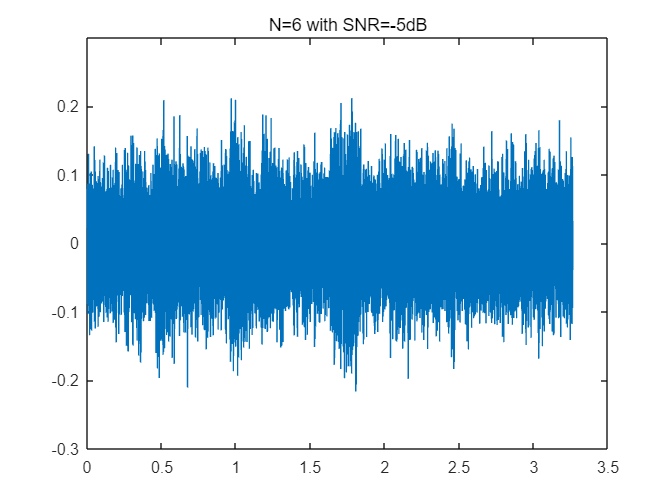

plot(xTime(y6_with_SSN,fs),y6_with_SSN),title('N=6 with SNR=-5dB'),ylim([-0.3,0.3])

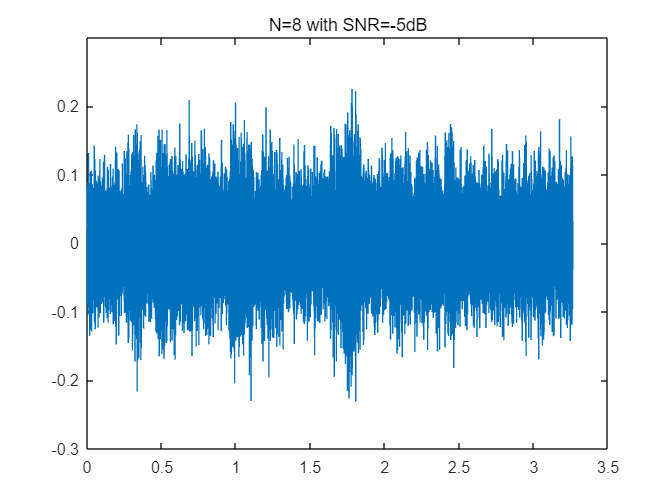

plot(xTime(y8_with_SSN,fs),y8_with_SSN),title('N=8 with SNR=-5dB'),ylim([-0.3,0.3])

**Task4**

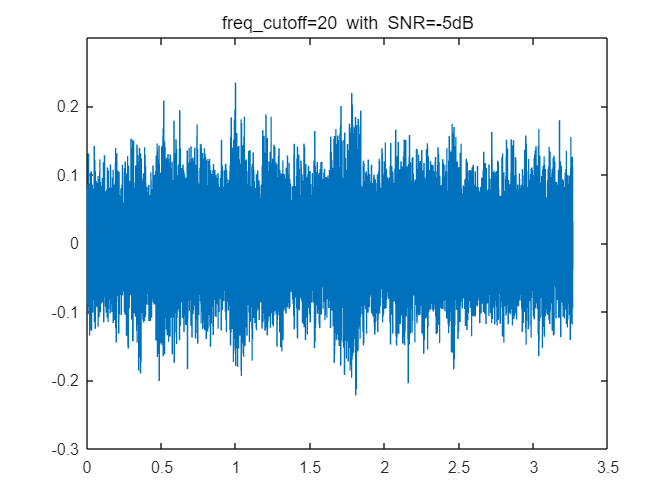

%set the number of bands to N=6
y_fs_20_with_SSN=Synthesize(x1,6,n1,n2,20,fs)+SSN;
y_fs_50_with_SSN=Synthesize(x1,6,n1,n2,50,fs)+SSN;
y_fs_100_with_SSN=Synthesize(x1,6,n1,n2,100,fs)+SSN;
y_fs_400_with_SSN=Synthesize(x1,6,n1,n2,400,fs)+SSN;

%Energy normalization
y_fs_20_with_SSN=y_fs_20_with_SSN/norm(y_fs_20_with_SSN)*norm(x1);
y_fs_50_with_SSN=y_fs_50_with_SSN/norm(y_fs_50_with_SSN)*norm(x1);
y_fs_100_with_SSN=y_fs_100_with_SSN/norm(y_fs_100_with_SSN)*norm(x1);
y_fs_400_with_SSN=y_fs_400_with_SSN/norm(y_fs_400_with_SSN)*norm(x1);

figure
plot(xTime(y_fs_20_with_SSN,fs),y_fs_20_with_SSN),title('freq\_cutoff=20 with SNR=-5dB'),ylim([-0.3,0.3])

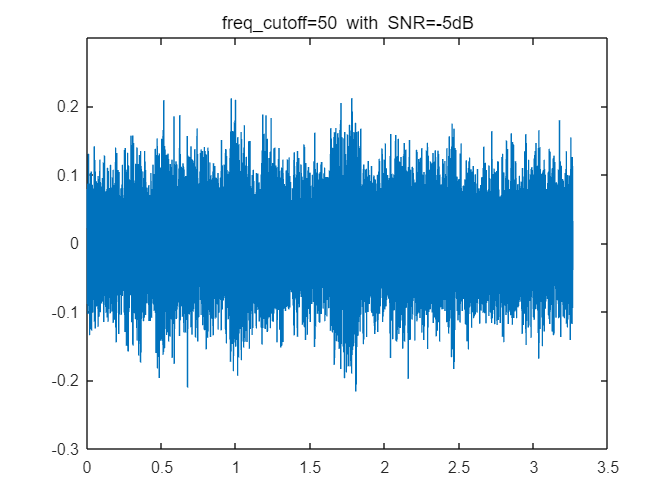

plot(xTime(y_fs_50_with_SSN,fs),y_fs_50_with_SSN),title('freq\_cutoff=50 with SNR=-5dB'),ylim([-0.3,0.3])

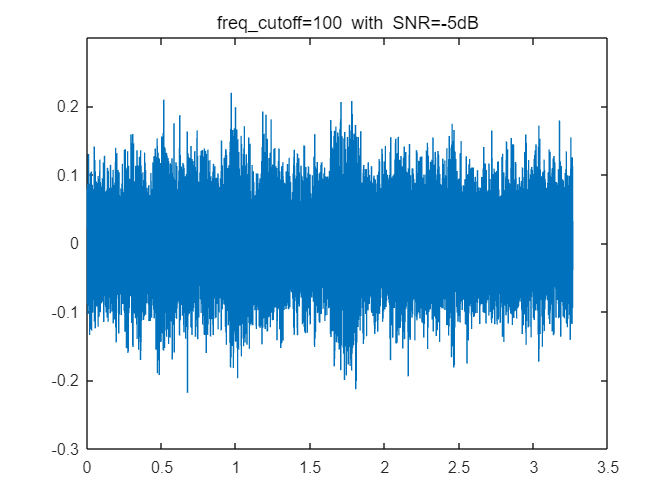

plot(xTime(y_fs_100_with_SSN,fs),y_fs_100_with_SSN),title('freq\_cutoff=100 with SNR=-5dB'),ylim([-0.3,0.3])

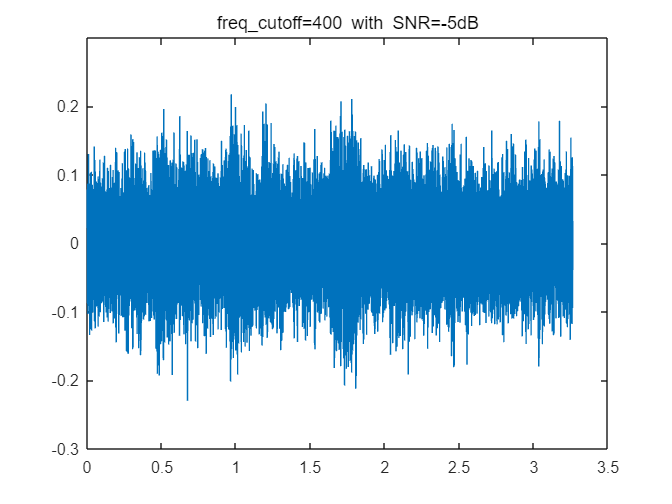

plot(xTime(y_fs_400_with_SSN,fs),y_fs_400_with_SSN),title('freq\_cutoff=400 with SNR=-5dB'),ylim([-0.3,0.3])

function t=xTime(x,fs)
    t=(0:length(x)-1)./fs;%将x轴用时间表示
end

function SSN=createSSN(x,fs)%上节课做的生成SSN
    x=x';
    sig=repmat(x,1,10);
    nfft=512;
    [Pxx,w]=pwelch(sig,hamming(nfft),nfft/2,nfft,fs);
    b=fir2(3000,w/(fs/2),sqrt(Pxx/max(Pxx)));
    white_noise=1-2*rand(1,length(x)+3000);
    SSN=filter(b,1,white_noise);
    SSN=SSN(2000:end);
    %Discard the beginning which has little sound.
    SSN=SSN(1:length(x));
end

function Fs=createBandDivision(N)

    %输入想要获得多少个带
    %Fs是每个带的频率区间，每个元素都是二元素向量
    fmin=200;
    fmax=7000;
    dmin=log10(fmin/165.4+1)/0.06;
    dmax=log10(fmax/165.4+1)/0.06;
    D=linspace(dmin,dmax,N+1);
    F=zeros(1,N+1);
    for k=1:N+1
        F(k)=165.4*(10^(0.06*D(k))-1);
    end
    Fs=zeros(N,2);
    for k=1:N
        Fs(k,:)=[F(k),F(k+1)];
    end
end

function y=Synthesize(x,N,n1,n2,fcut,fs)
    %输入音频x，切割带数N，n1带通滤波阶数，n2低通滤波阶数
    Fs=createBandDivision(N);
    y=zeros(1,length(x));

    for k=1:N
        [b1,a1]=butter(n1,Fs(k,:)/(fs/2),"bandpass");
        y_filtered=filter(b1,a1,x);

        [b2,a2]=butter(n2,fcut/(fs/2),'low');
        %取包络选择什么滤波器？？？？？？？？？？？？？？？？？？？阶数？？？？？？？？？？？？？？？？？？？？？？
        y_env=filter(b2,a2,abs(y_filtered));

        sine_wave_freq=(Fs(k,1)+Fs(k,2))/2;
        sine_wave=sin(2*pi*sine_wave_freq*xTime(y_env,fs));

        y_modulation=y_env'.*sine_wave;

        y=y+y_modulation;
        y=y./norm(y).*norm(x);
    end
end